# Run SDO

## Overview

Requires: a ppDataCell, an xtDataCell, selected indices, 

Returns: SDOs, significance of SDOs, selected graphs

## Imports and Setup

Make SDO

SDO = sdoMultiMat;


Set the dataset, channels and specify the neurons you want to analyze

input_data = ppdc_subset;
channel_idx = idx;
neurons = 185:198;

%Selects the specified neurons across trials
ntrials = input_data.nTrials; 
input_subset = input_data.subsample(1:ntrials, neurons);
%nchannels = input_subset.nChannels;

Import the EMG data to compare with the neurons, could choose force data instead. Set xtdc_idx to select muscles or force directions to include.

xtdc = xtDataCell;

% Compare to EMG
%{
xtdc.import(emgCell);
xtdc_idx = 1:11;
%}


%Compare to Force
xtdc.import(forceDataCell);
xtdc.mapMethod = 'linearsigned';
xtdc_idx = 1:6;

%Regardless of which one
xtdc_subset = xtdc.subsample(channel_idx, xtdc_idx);


Clean the input data so only trials with enough spikes are processed, can set the threshold

threshold = 200;
channel_sum = sum(input_subset.nTrialEvents, 2);
keep_indexes = (channel_sum >= threshold);
large_idx = find(keep_indexes);
input_subset = input_subset.subsample(1:ntrials, large_idx);


## Compute the SDO 

This will take some time proportional to the number of trials and channels selected

SDO.compute(xtdc_subset, input_subset);

Elapsed time is 3.439837 seconds.
Finished Ch#1/6
Elapsed time is 3.312690 seconds.
Finished Ch#2/6
Elapsed time is 3.465666 seconds.
Finished Ch#3/6
Elapsed time is 3.573142 seconds.
Finished Ch#4/6
Elapsed time is 3.470698 seconds.
Finished Ch#5/6
Elapsed time is 3.429805 seconds.
Finished Ch#6/6


### Find the significant SDOs

SDO.findSigSdos;
SigSDOs = SDO.findSigSdos;

### Plots

Plot the EMG or Force Data

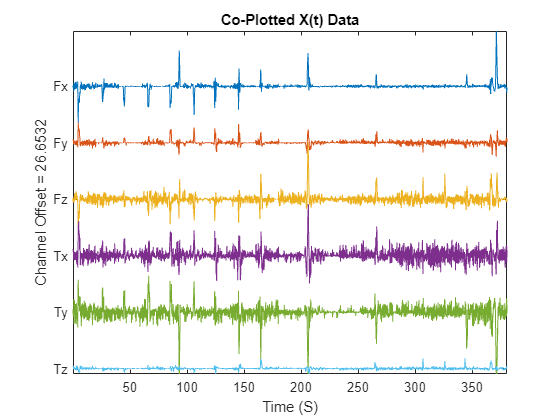

xtdc_subset.plot(1:ntrials, xtdc_idx);

Plot the SDO

Plotting Tz x channel78_unit2


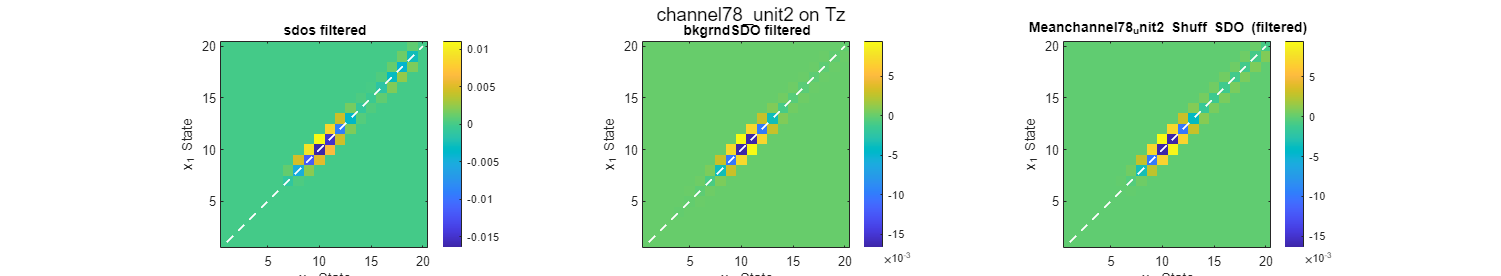

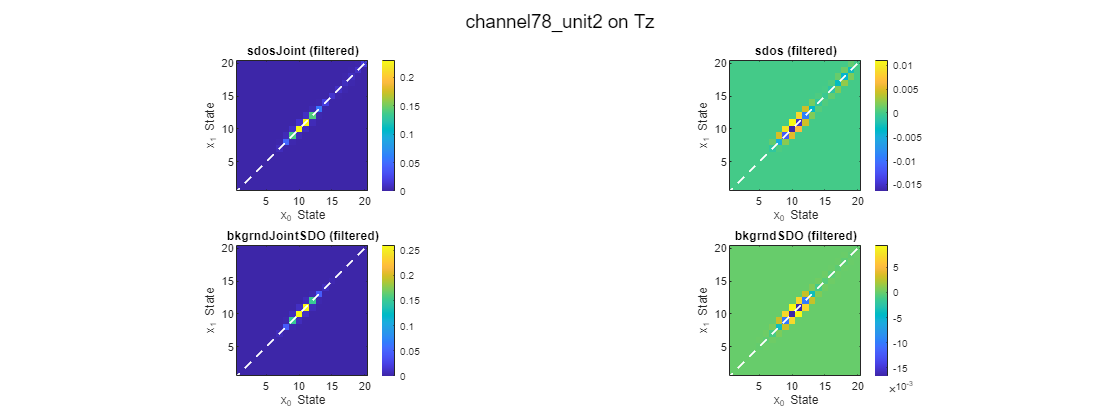

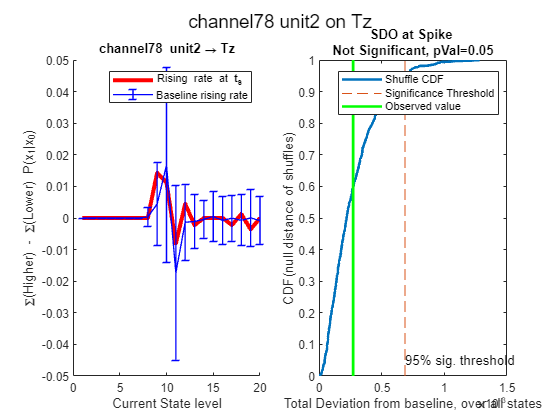

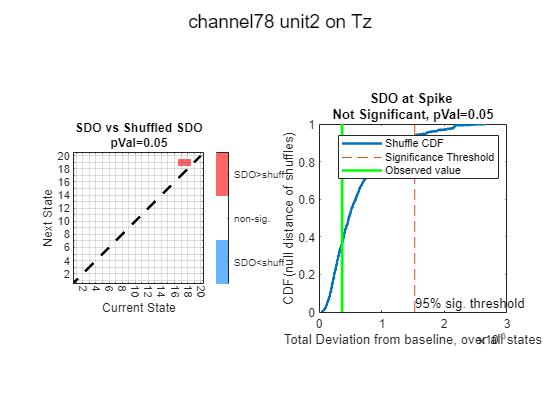

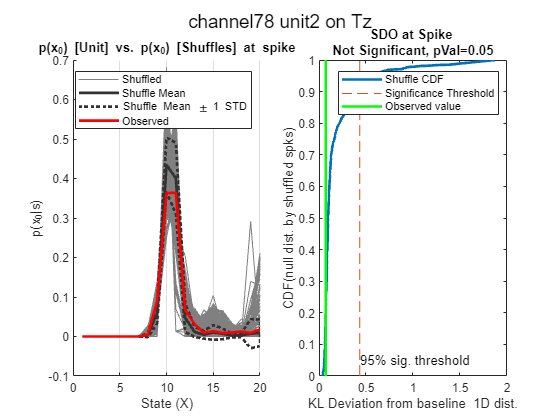

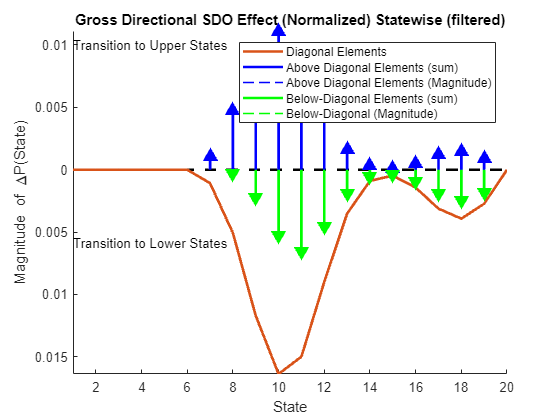

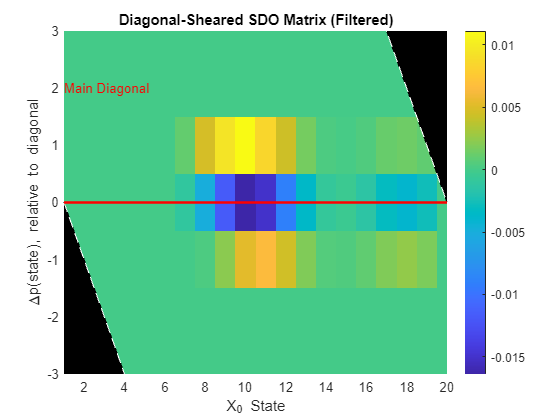

%should make this into an iteration rather than plotting just the first and
%second elements of the selected channels
SDO_extracted = SDO.extract(max(xtdc_idx), 1);
SDO_extracted.plot

### Plot Significant SDOs

Plot the SDOs for which  number of significant tests >1


li = [SDO.sigMat.nSigValues] >1;
miniSig = SDO.sigMat(li); 
for r = 1:size(miniSig, 2)
    SDO.plot(miniSig(r).xtChannelNo, miniSig(r).ppChannelNo); 
end

